# Analyzing the Visual Coding 2P Dataset from the Allen Brain Observatory 

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding 2P dataset [2] consists of neural activity recordings obtained using two-photon calcium imaging:

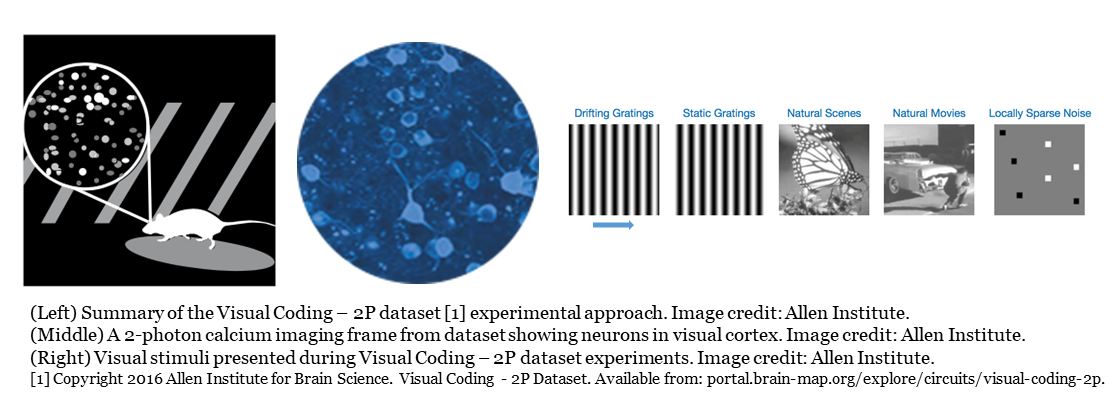

These recordings were obtained from a range of mouse visual areas, at a range of imaging depths, with indicator expressions produced under several transgenic lines, and using a number of visual stimuli. For detailed information about experimental conditions and stimuli to date, see the Visual Coding 2P dataset website: [https://portal.brain-map.org/explore/circuits/visual-coding-2p](https://portal.brain-map.org/explore/circuits/visual-coding-2p). 

This example shows how to perform some simple analyses of visual responses by neurons in the mouse primary visual cortex. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

Note the Image Processing Toolbox and the Statistics and Machine Learning Toolbox are required for this demonstration. 

### **Filtering by cortical area and layer, visual stimulus, and behavioural tracking**

Our goal for this example is to analyse visually responsive neurons in the primary visual cortex (V1) for orientation and direction selectivity. These selectivities are reported to be most pronounced in the anterolateral (AL), rostrolateral (RL), and anteromedial (AM) areas of V1 [3]. This analysis seeks a dataset from these areas in which drifting grating stimuli were presented and where the behavioural state of the animal was tracked.

% obtain the manifest table of experimental sessions
sessions = bot.fetchSessions('ophys');

% select experiments from the most orientation/direction-selective areas of visual cortex 
sessions = sessions(ismember(sessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);

% select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
sessions = sessions(sessions.cre_line == "Cux2-CreERT2", :);

% select experiments imaging from the shallowest depth in Layer 2/3
sessions = sessions(sessions.imaging_depth == 175,:);

% select experiments with eye tracking data available
sessions = sessions(~sessions.fail_eye_tracking, :);

% select experiments with drifting grating and natural movie stimuli
sessions = sessions(sessions.stimulus_name == "three_session_A", :);

% select first session, which was obtained by Allen Institute researchers in February 2016
session = bot.session(sessions(1,:));

### Extracting neuron cell body regions-of-interest (ROIs) from imaged volume

Let's look at the imaged field by visualizing the maximum intensity projection of the image volume. By examining the session metadata, we can see the field of view is 400x400µm (512x512 pixels).

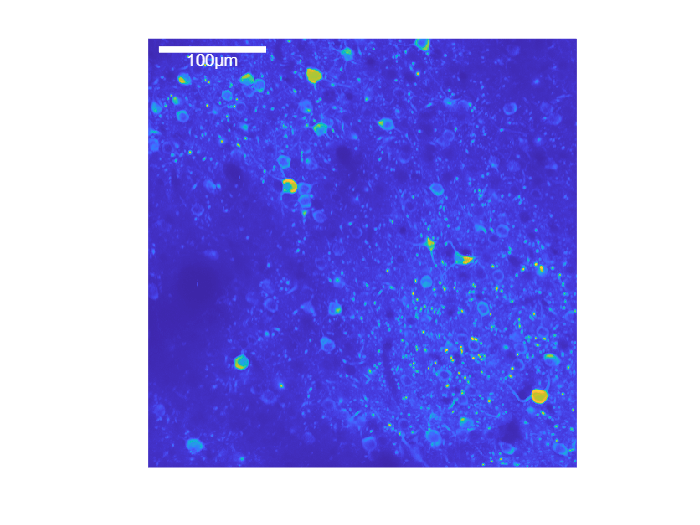

pixelSize = 400/512;
xLocations = linspace(0, 400-pixelSize, 512) + pixelSize / 2;
figure;
imagesc(xLocations, xLocations, session.max_projection);
colormap default;
axis square tight off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

We can access the locations and shapes of ROIs defining each neuron's cell body using the `get_roi_mask `method which returns these ROIs as a 3-D connected components structure (`bwconncomp`). These can be plotted and manipulated by Image Processing Toolbox commands such as `labelmatrix.`

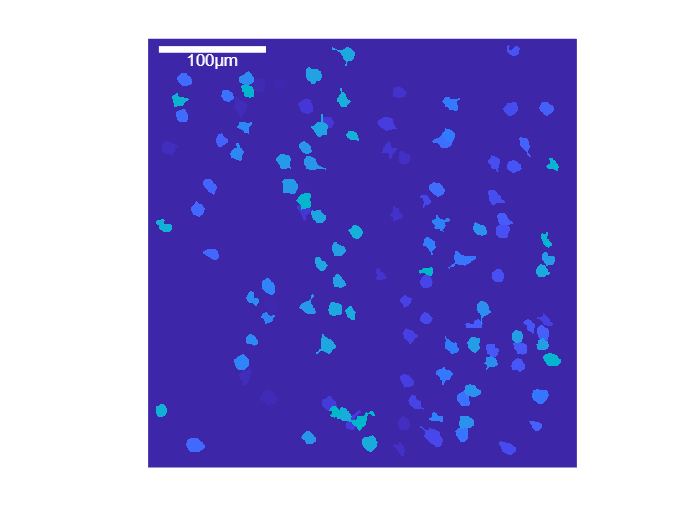

ROIs = session.roi_mask;
figure;
image(xLocations, xLocations, labelmatrix(ROIs));

axis tight square off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

### Assessing neuron responses via calcium imaging fluorescence signals

To access the fluorescence signals for each of the neuron ROIs, the `get_dff_traces()` method is used.

timestamps = session.fluorescence_timestamps

timestamps = 115744×1 duration array
   9.9738 sec
   10.007 sec
    10.04 sec
   10.073 sec
   10.106 sec
    10.14 sec
   10.173 sec
   10.206 sec
   10.239 sec
   10.272 sec
   10.305 sec
   10.339 sec
   10.372 sec
   10.405 sec
   10.438 sec
   10.471 sec
   10.504 sec
   10.538 sec
   10.571 sec
   10.604 sec
   10.637 sec
    10.67 sec
   10.704 sec
   10.737 sec
    10.77 sec
   10.803 sec
   10.836 sec
   10.869 sec
   10.903 sec
   10.936 sec


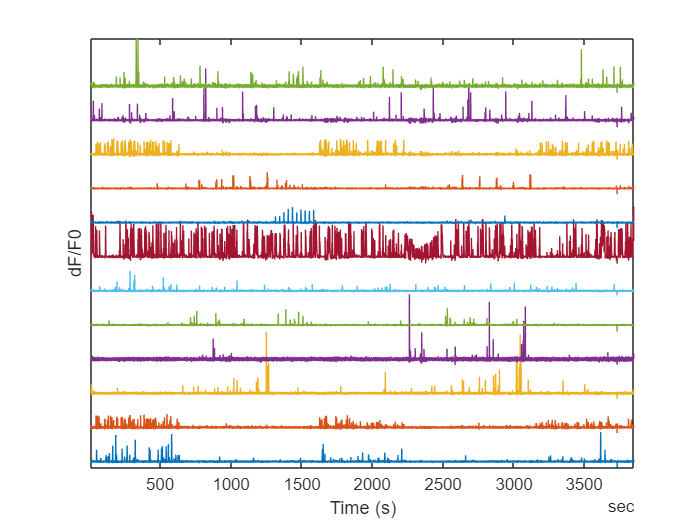

traces = session.fluorescence_traces_dff;
figure;
plot(session.fluorescence_timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

Not all neurons respond equally, as is clear from the traces above. One approach to select ROIs with robust responses is to measure the sample skewness of the individual responses over time. Neurons that fire sparsely result in a rapid spike in fluorescence emitted photons, followed by an exponential decay of fluorescence down to the noise level of the system. The resulting distribution of recorded fluorescence values has a positively skewed distribution, compared with normally distributed white noise which has a theoretical skewness of zero. We can use the `skewness` function from the Statistics and Machine Learning Toolbox to estimate the sample skewness for each ROI.

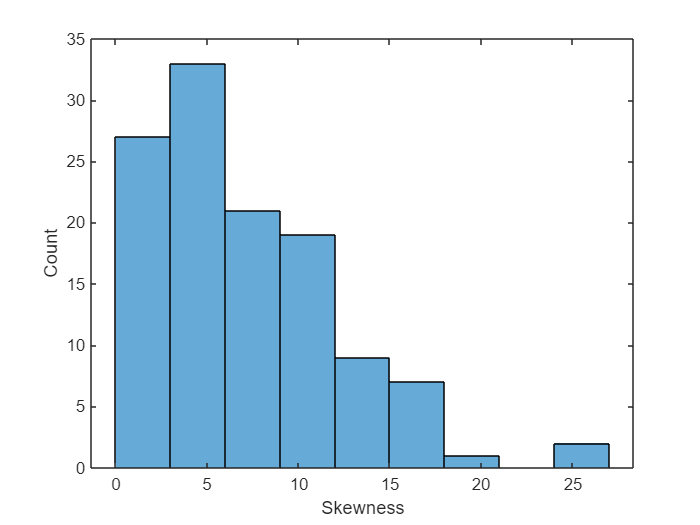

respSkewness = skewness(traces);
figure;
histogram(respSkewness);
xlabel('Skewness'); ylabel('Count')

Compare the response of a high-skewness ROI with that of a low-skewness ROI:

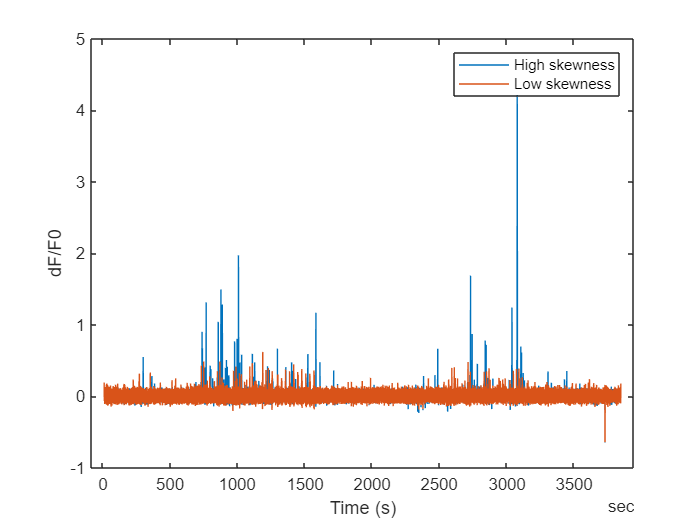

[~, sortOrder] = sort(respSkewness);
figure;
plot(timestamps, traces(:, sortOrder([end 5])))
xlabel('Time (s)'); ylabel('dF/F0');
legend('High skewness', 'Low skewness');

Generally a skewness threshold of 1 or 2 is sufficient, which is passed by the majority of neurons in this experiment.

### Analyzing neuron stimulus responses for varying synthetic visual stimuli

The particular animal's responses to individual trials of the drifting gratings stimuli, separated by drift direction, can now be found.

% get the stimulus information for drifting grating responses
driftingGratings = session.getStimulusTable('drifting_gratings');

% use a utility function to estimate single-trial responses for each stimulus
responses = bot.util.StimulusAlignedResp(driftingGratings, traces);

% locate "blank" stimulus presentations
blankPresentations = driftingGratings.blank_sweep == 1;

% extract neural responses to blank presentations
blankResponses = mean(responses(blankPresentations, :),'omitnan');

% subtract blank responses
responsesCorrected = responses - blankResponses;

Each particular visual stimulus was presented multiple times, so we therefore need to collect and sort responses to multiple trials of the same visual stimulus.

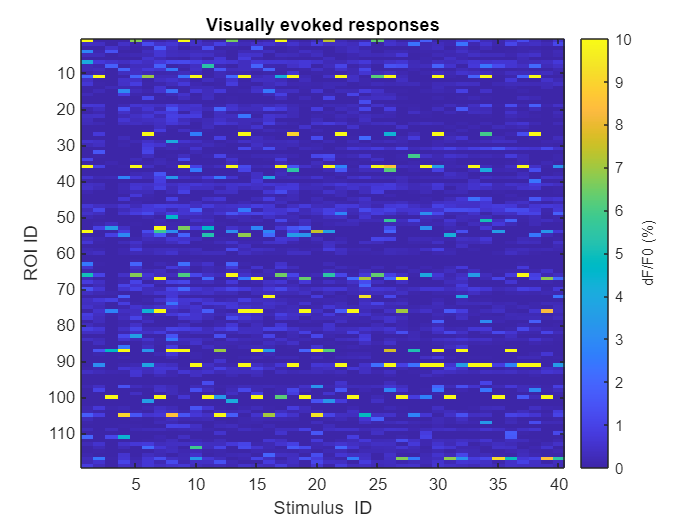

% get a list of unique stimulus parameters and assign a stimulus ID to each presentation
driftingGratingsTbl = timetable2table(driftingGratings,"ConvertRowTimes",false);
[uniqueStimuli, ~, presentationStimID] = unique(driftingGratingsTbl(:, 1:2), 'rows', 'sorted');

% find NAN stimuli and remove them
nanStimuli = isnan(uniqueStimuli.temporal_frequency);
uniqueStimuli = uniqueStimuli(~nanStimuli, :);
numStimuli = size(uniqueStimuli, 1);
numROIs = size(responsesCorrected, 2);

% preallocate arrays
singleTrialResponses = cell(numStimuli, 1);
meanStimulusResponses = nan(numStimuli, numROIs);
varStimulusResponses = nan(numStimuli, numROIs);

% collect single-trial responses for each stimulus
for stimulusID = 1:size(uniqueStimuli, 1)
    % find the presentations of this stimulus
    theseTrials = presentationStimID == stimulusID;
    
    % collect all the fluorescence responses for this stimulus into a cell array
    singleTrialResponses{stimulusID} = responsesCorrected(theseTrials, :);
    
    % estimate response statistics for this stimulus
    meanStimulusResponses(stimulusID, :) = mean(singleTrialResponses{stimulusID},'omitnan');
    varStimulusResponses(stimulusID, :) = var(singleTrialResponses{stimulusID},'omitnan');
end

% visualize the mean responses
figure;
imagesc(meanStimulusResponses' * 100);
xlabel('Stimulus  ID');
ylabel('ROI ID');
title('Visually evoked responses')
caxis([0 10]);
ax = colorbar;
ylabel(ax, 'dF/F0 (%)')

### Computing direction selectivity and orientation selectivity of individual neurons

Now, we are able to assign a selectivity measure of directional tuning to each ROI ([Hashemi-Nezhad & Lyon 2011](http://dx.doi.org/10.1093/cercor/bhr105)). These values range between 0 and 1, and indicate how strongly a ROI prefers a particular visual stimulus over others. Values close to 0 indicate no preference. Values close to 1 indicate a strong selective prefence for some stimuli.

We will estimate two metrics — one to test whether ROIs prefer particular directions of drift of the moving gratings (a "direction selectivity index" or DSI); the second tests whether ROIs prefer particular orientations of the gratings, regardless of drift direction (an "orientation selectivity index" or OSI).

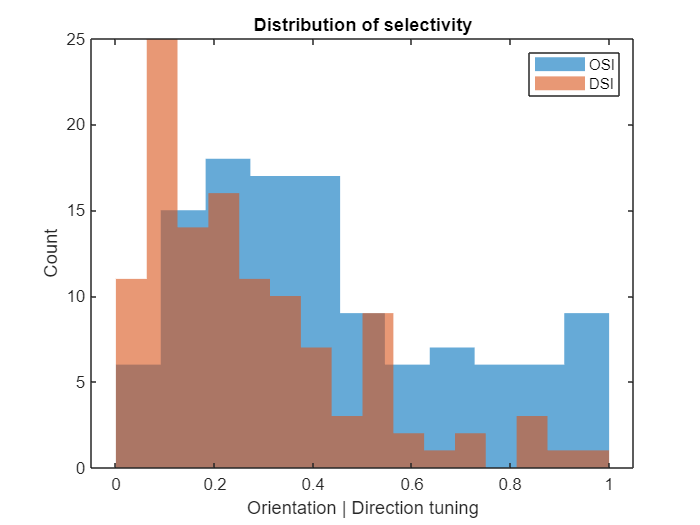

% generate direction and orientation selectivity indices
stimDirection = exp(-1i * deg2rad(uniqueStimuli.orientation));
stimOrientation = exp(-1i * deg2rad(2*uniqueStimuli.orientation));
dirSelectivityIndex = abs(sum(max(0, meanStimulusResponses) .* stimDirection)) ./ sum(max(0, meanStimulusResponses));
oriSelectivityIndex = abs(sum(max(0, meanStimulusResponses) .* stimOrientation)) ./ sum(max(0, meanStimulusResponses));

% plot the distribution of selectivity indices
figure;
bins = linspace(0, 1, 15);
histogram(oriSelectivityIndex, linspace(0, 1, 12), 'EdgeColor', 'none');
hold all;
histogram(dirSelectivityIndex, linspace(0, 1, 17), 'EdgeCOlor', 'none');
xlabel('Orientation | Direction tuning');
ylabel('Count');
title('Distribution of selectivity');
legend('OSI', 'DSI');

We can see that more neurons are orientation-tuned (high values for OSI, in blue), than direction tuned (high values for DSI, in orange), as described in prior literature [3]. 

### Plotting tuning curves

We now examine the responses and tuning of neurons by plotting tuning curves for direction and for temporal frequency. 

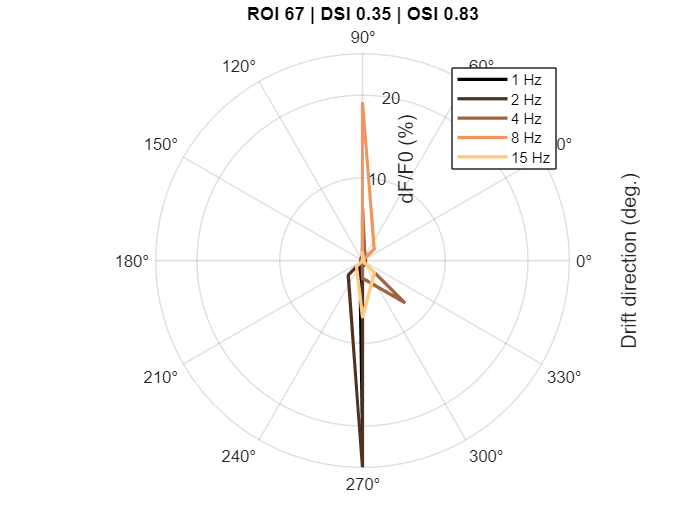

% determine preferred direction for each ROI
dirPreference = angle(sum(max(0, meanStimulusResponses) .* stimDirection));
[~, dirSortOrder] = sort(dirPreference);

% plot tuning curves for an interesting ROI
neuronIDPlot = 67;
figure;
plot_dir_tuning_curve(neuronIDPlot, uniqueStimuli, meanStimulusResponses);
title(sprintf('ROI %d | DSI %.2f | OSI %.2f', neuronIDPlot, dirSelectivityIndex(neuronIDPlot), oriSelectivityIndex(neuronIDPlot)))

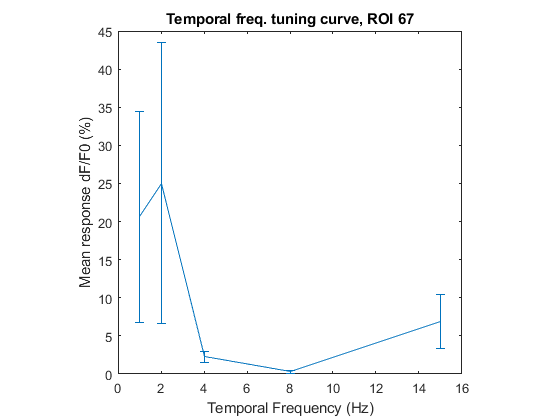

% plot a temporal frequency tuning curve at preferred direction, showing SEM over single-trial responses
figure;
plot_tf_tuning_curve(neuronIDPlot, driftingGratings, responses);

The TF tuning curve is plotted for the stimuli matching the ROI's preferred drift direction. We can see that this ROI responds more strongly to faster drifting gratings (higher temporal frequency).

#### **Interactive tuning curve plot**

Generate a tuning curve figure and update the plotted data on the fly without generating a new figure:

% pre-compute several tuning curves for highly-tuned neurons
useNeurons = max(oriSelectivityIndex, dirSelectivityIndex) > 0.7;
useNeurons = useNeurons & max(meanStimulusResponses) > .1;
[dirTuningCurves, temporalFrequencies, driftDirections] = ...
    dir_tuning_curves(uniqueStimuli, meanStimulusResponses(:, useNeurons));
curves = [];

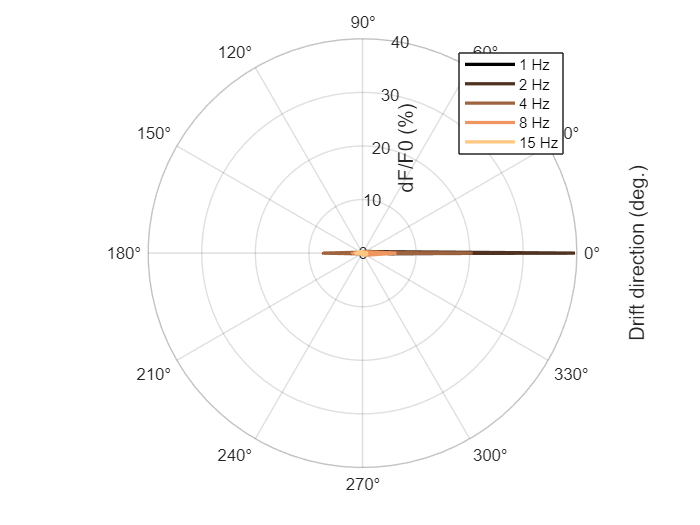

% quickly update the tuning curve to show a different ROI
neuronIDPlot = 1;
if neuronIDPlot > nnz(useNeurons), neuronIDPlot = nnz(useNeurons); end
curves = update_tuning_curve(curves, dirTuningCurves(:, :, neuronIDPlot) * 100, uniqueStimuli, meanStimulusResponses);

### Assessing correlation of pupil diameter behavioural signals with neural signals

Here, we examine changes in pupil size over time, which is considered by some to be a measure of attention or arousal ([van den Brink et al. 2016](https://doi.org/10.1371/journal.pone.0165274) and references therein).

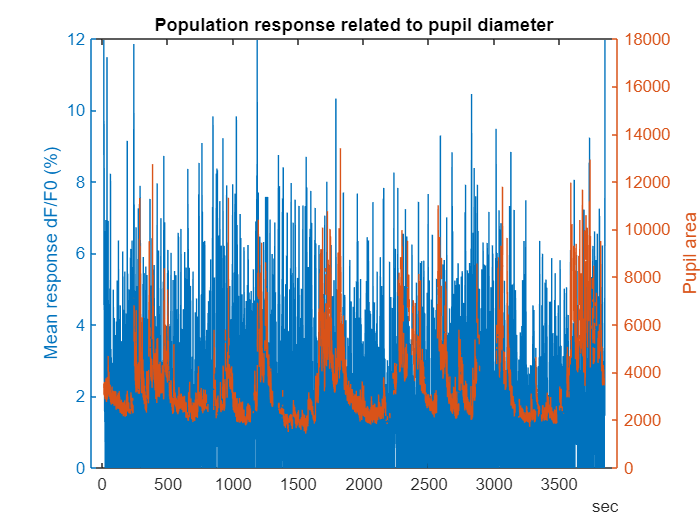

% get a pupil area trace
pupilArea = session.pupil_size;

% visualize the pupil area over time, along with population mean activity
meanRespPop = mean(traces, 2,'omitnan');
figure;
yyaxis left;
plot(timestamps, meanRespPop * 100);
ylim([0 12]);
ylabel('Mean response dF/F0 (%)');
yyaxis right;
plot(pupilArea.timestamps,pupilArea.pupil_areas);
ylabel('Pupil area');
title('Population response related to pupil diameter');

Then, the neuron response associated with pupil area can be visualized.

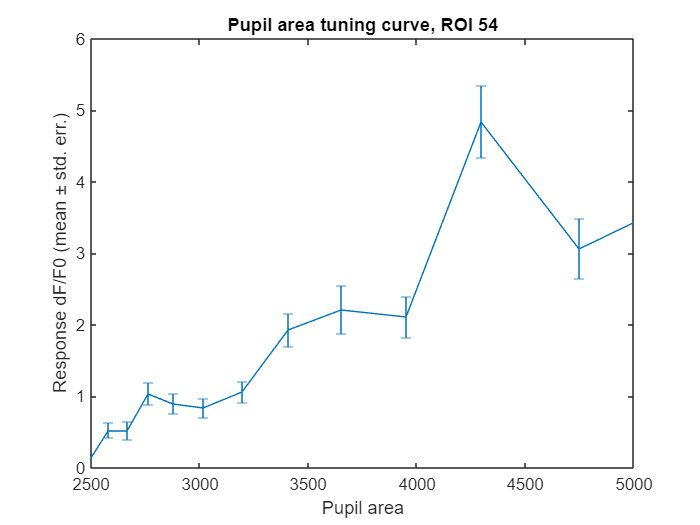

% find a neuron that correlates with pupil area
pupilCorr = corr(pupilArea.pupil_areas, traces, 'rows', 'complete');
[~, neuronID] = max(pupilCorr);

% bin time according to pupil diameter, with equal samples per bin
numBins = 20;
binsPupil = prctile(pupilArea.pupil_areas, linspace(0, 100, numBins));
binCentresPupil = (binsPupil(1:end-1) + binsPupil(2:end)) / 2;
assignBins = discretize(pupilArea.pupil_areas, binsPupil);
useBins = ~isnan(assignBins);
meanRespPupil = accumarray(assignBins(useBins), traces(useBins, neuronID), [], @(x)mean(x,'omitnan'));
stdRespPupil = accumarray(assignBins(useBins), traces(useBins, neuronID), [], @(x)std(x,'omitnan'));
binCounts = accumarray(assignBins(useBins), 1);

% visualize neuron response associated with pupil area
figure;
errorbar(binCentresPupil, 100 * meanRespPupil, 100 * stdRespPupil ./ sqrt(binCounts));
xlim([.25 .5]*1e4);
xlabel('Pupil area');
ylabel('Response dF/F0 (mean ± std. err.)');
title(sprintf('Pupil area tuning curve, ROI %d', neuronID));

### Examining natural movie responses

Many experimental sessions also contain activity recorded in response to natural movie stimuli, and these responses can be visualized and plotted.

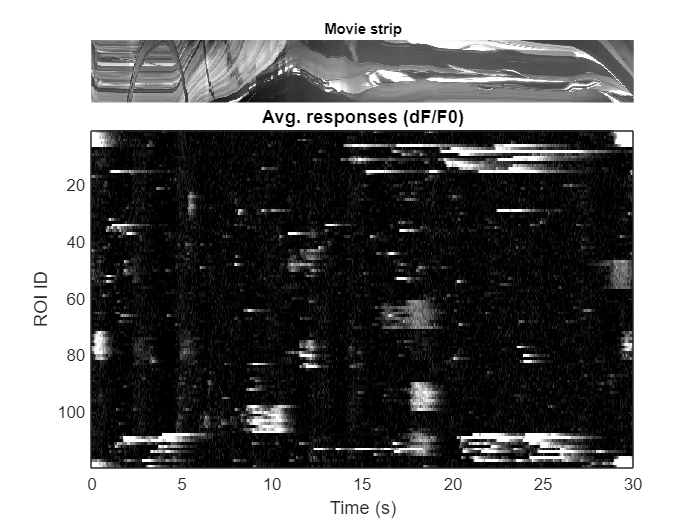

% get the stimulus information for a natural movie stimulus
naturalMovieOne = session.getStimulusTable('natural_movie_one');

% use a utility function to estimate single-trial responses for each stimulus
responsesMovie = bot.util.StimulusAlignedResp(naturalMovieOne, traces, [], [], true);

% reshape into tensor of [movie frame, ROI, trial]
numTrials = max(naturalMovieOne.repeat) + 1;
responsesMovie = reshape(responsesMovie, [], numROIs, numTrials);
numMovieFrames = size(responsesMovie, 1);
meanRespMovie = mean(responsesMovie, 3, 'omitnan');

% get the movie frames from the stimulus
movie = session.getStimulusTemplate('natural_movie_one');

% make a time trace for the movie
startTime = timestamps(naturalMovieOne.start_frame(1));
endTrialFrame = find(naturalMovieOne.repeat == 0, 1, 'last');
endTime = timestamps(naturalMovieOne.end_frame(endTrialFrame));
endTime = endTime - startTime;
timeTraceMovie = seconds(linspace(0, endTime, numMovieFrames));

% make a figure showing the mean responses
figure;
subplot(5, 1, 1);
imagesc(make_movie_strip(movie));
colormap gray
title('Movie strip')
axis off;
subplot(5, 1, 2:5);
imagesc(timeTraceMovie, 1:numROIs, meanRespMovie' * 100);
title('Avg. responses (dF/F0)');
xlabel('Time (s)');
ylabel('ROI ID');
caxis([0 20]);

#### **Estimating response reliability**

We can generate a metric for response reliability, using trial-to-trial correlations in response to natural movie stimuli. This will help us pick out ROIs that are visually responsive to natural movies, under the assumption that they should respond similarly across trials.

Response reliability is defined as the average pairwise correlation coefficient between time traces of all single-trial responses for a given ROI.

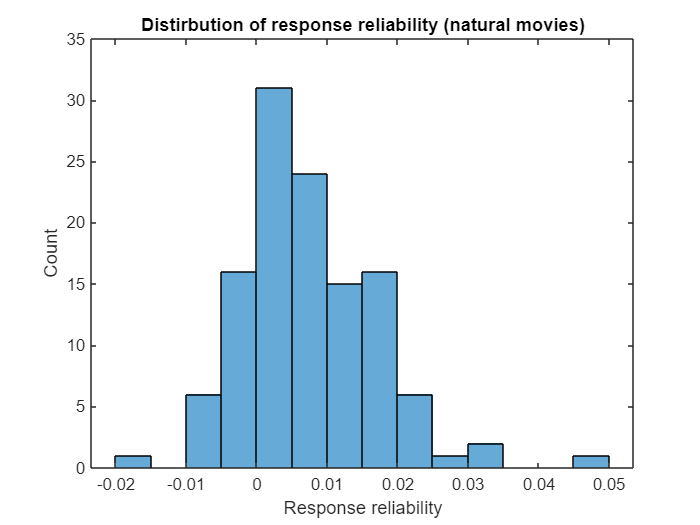

% compute response reliability
reliabilityMovie = nan(1, numROIs);
for roiID = 1:numROIs
    reliabilityMovie(roiID) = movie_response_reliability(responsesMovie(:, roiID, :));
end

% show a histogram of response reliabilities
figure;
histogram(reliabilityMovie);
title('Distirbution of response reliability (natural movies)')
xlabel('Response reliability');
ylabel('Count');

#### **Plotting the single-trial natural movie responses for a cell**

Trial-to-trial correlations are fairly low for most ROIs. Let's show the responses of one ROI that responds strongly, and has a relatively high response reliability.

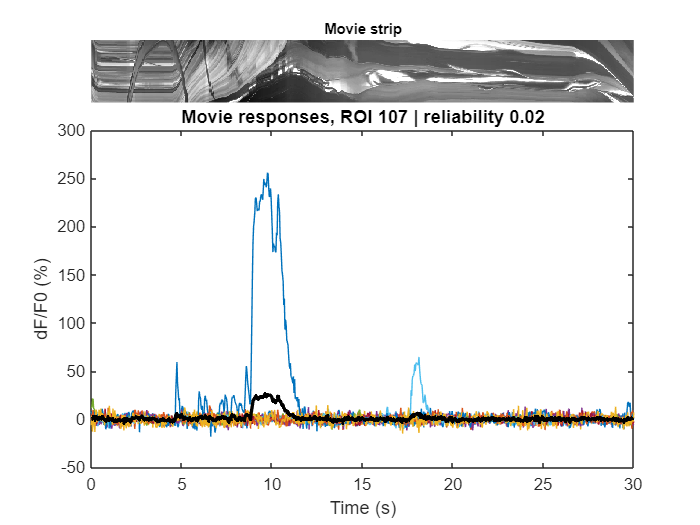

% plot the single-trial responses for a single cell
cellID = 107;

figure;
subplot(5, 1, 1);
imagesc(make_movie_strip(movie));
colormap gray;
title('Movie strip')
axis off;
subplot(5, 1, 2:5);
plot(timeTraceMovie, squeeze(responsesMovie(:, cellID, :)) * 100);
hold all;
plot(timeTraceMovie, meanRespMovie(:, cellID) * 100, 'k-', 'LineWidth', 2);
xlim(seconds([0 endTime]))
title(sprintf('Movie responses, ROI %d | reliability %.2f', cellID, reliabilityMovie(cellID)));
xlabel('Time (s)');
ylabel('dF/F0 (%)');

### Conclusion

This demo illustrates simple analyses of neural responses, such as orientation tuning, using the BOT. For more details about the BOT methods and properties associated with each item, see the ophys tutorial.

### Utility functions

function [dirTuningCurves, temporalFrequencies, driftDirections] = ...
    dir_tuning_curves(uniqueStimuli, meanStimulusResponses)
    % function to calculate direction tuning curves over temporal frequencies
    
    % extract temporal frequencies and drift directions
    [temporalFrequencies, ~, tempFreqIDs] = unique(uniqueStimuli.temporal_frequency);
    temporalFrequencies = temporalFrequencies(~isnan(temporalFrequencies));
    [driftDirections, ~, driftDirIDs] = unique(uniqueStimuli.orientation);
    driftDirections = deg2rad(driftDirections);
    
    % make an index for ROI ID
    numROIs = size(meanStimulusResponses, 2);
    roiIDs = permute(1:numROIs, [2 3 1]);
    [tempFreqIndex, roiIndex] = ndgrid(tempFreqIDs, roiIDs);
    [driftDirIndex, ~] = ndgrid(driftDirIDs, roiIDs);
    
    % clip responses at zero
    meanStimulusResponses = max(0, meanStimulusResponses);
    
    % build a tensor of tuning curves
    dirTuningCurves = accumarray(...
        {driftDirIndex(:), tempFreqIndex(:), roiIndex(:)}, ...
        meanStimulusResponses(:), ...
        [numel(driftDirections), numel(temporalFrequencies), numROIs]);
end

function curves = plot_dir_tuning_curve(exampleROI, uniqueStimuli, meanStimulusResponses)
    % function to plot a direction tuning curve

    % get a tuning curve for this ROI
    [dirTuningCurves, temporalFrequencies, driftDirections] = ...
        dir_tuning_curves(uniqueStimuli, meanStimulusResponses(:, exampleROI));
    
    % make a color map for the temporal frequencies
    colors = copper(length(temporalFrequencies));
    
    % loop over temporal frequencies
    for temporalFreqID = 1:length(temporalFrequencies)
        curves(temporalFreqID) = polarplot(driftDirections([1:end 1]), dirTuningCurves([1:end 1], temporalFreqID) * 100, ...
                  'LineWidth', 2, ...
                  'Color', colors(temporalFreqID, :)); %#ok<AGROW> 
        hold on;        
    end
    
    % make the plot prettier
    a = gca;
    a.RAxis.Label.String = 'dF/F0 (%)';
    a.ThetaAxis.Label.String = 'Drift direction (deg.)';
    
    % add a temporal frequency legend
    legendText = arrayfun(@(tf)sprintf('%d Hz', tf), temporalFrequencies, 'UniformOutput', false);
    legend(legendText, 'location', 'northeast');
end

function curves = update_tuning_curve(curves, newTuningCurve, uniqueStimuli, meanStimulusResponses)
    % function to generate or update a tuning curve plot
    if isempty(curves)
        figure;
        curves = plot_dir_tuning_curve(1, uniqueStimuli, meanStimulusResponses);
    end
    
    % function to modify an existing tuning curve plot
    for temporalFreqID = 1:size(newTuningCurve, 2)
        curves(temporalFreqID).RData = newTuningCurve([1:end 1], temporalFreqID);
    end    
end

% function to plot a temporal frequency tuning curve at the preferred direction
function plot_tf_tuning_curve(exampleROI, stimuli, responses)
    % find the preferred direction for the chosen ROI
    respROI = responses(:, exampleROI);
    [~, ~, directionID] = unique(stimuli.orientation);
    sumRespDir = accumarray(directionID, respROI);
    [~, prefDir] = max(sumRespDir,[],'omitnan');
    prefDirResps = directionID == prefDir;
    
    % collect responses over temporal frequencies
    [temporalFrequencies, ~, tfIDs] = unique(stimuli.temporal_frequency(prefDirResps));
    meanRespTF = accumarray(tfIDs, respROI(prefDirResps), [], @(x)mean(x,'omitnan'));
    stdRespTF = accumarray(tfIDs, respROI(prefDirResps), [], @(x)std(x,'omitnan'));
    countRespTF = accumarray(tfIDs, 1);
    
    % plot TF tuning curve
    errorbar(temporalFrequencies, 100* meanRespTF, 100 * stdRespTF ./ sqrt(countRespTF));
    xlabel('Temporal Frequency (Hz)');
    ylabel('Mean response dF/F0 (%)');
    title(sprintf('Temporal freq. tuning curve, ROI %d', exampleROI));
    xlim([0 max(temporalFrequencies)+1]);
    axis square;
end

% function to generate a natural movie strip
function strip = make_movie_strip(movie)
    halfFrame = round(size(movie, 2) / 2);
    strip = squeeze(movie(:, halfFrame, :));
end

function reliability = movie_response_reliability(responses)
    % function to compute response reliability
    % `responses` is [time x trials]
    corrs = corrcoef(squeeze(responses));
    takeCorrs = triu(true(size(corrs)), 1);
    reliability = mean(corrs(takeCorrs),'omitnan');
end

### References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [portal.brain-map.org/explore/circuits/visual-coding-2p](https://portal.brain-map.org/explore/circuits/visual-coding-2p).

[3] Marshal, J.H., Garrett, M.E., Nauhaus, I., and Callaway, E.M. (2011). Functional Specialization of Seven Mouse Visual Cortical Areas. *Neuron* 72 (6): 1040. [https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004](https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004).